##  一.学习算法应用

## 1.理解多目标粒子遗传算法

- 了解了其具体在Matlab上的代码含义

- 确定了目标种群初始化生成方法  

**1. ****确定种群规模**

- 种群规模由 `options.PopulationSize` 决定。假设种群大小为 `N` 且变量数为 `nvars`，那么初始种群矩阵的维度应为 `N × nvars`。

**  2. ****生成初始种群的矩阵**

- 阵列120个麦克风，以单臂上每个麦克风的半径rn作为优化变量，整个阵列由单臂旋转的到

每个臂上有8个麦克风，共15个臂。则变量的维度为`nvars`=8。

- 每一个rn应被限制在一定的范围内，由上下界`ub`,`lb`确定

- 考虑加入旋转角作为一个维度（暂时不实现）

- 如果希望种群随机分布，可以使用 `rand` 。

- 如果有部分已知的解，可以将这些解作为初始值的一部分。可以先确定一组rn位置,作为已知解，生成初始的种群

nvars = 8;         % 变量维度
N = 200;           % 种群大小（与 options.PopulationSize 一致）
lb = [0.01,0.01721, 0.034, 0.04,0.05,0.06,0.068,0.078]; % 下界
ub =  [0.016, 0.03 0.0384, 0.0496,0.0587,0.06656,0.07350,08]; % 上界

`% 随机生成初始种群`

initialPopulation = repmat(lb, N, 1) + rand(N, nvars) .* (repmat(ub - lb, N, 1));
% 假设已知解 knownSolutions
knownSolutions = [10, 20, 30, 40; 50, 60, 70, 80]; % 两组已知解
initialPopulation(1:size(knownSolutions, 1), :) = knownSolutions;

**  3. ****设置初始种群选项**

  使用 `optimoptions` 设置 `InitialPopulationMatrix`：

options = optimoptions(@gamultiobj, ...
    'PopulationSize', N, ...
    'InitialPopulationMatrix', initialPopulation, ...
    'Generations', 300, ...
    'PlotFcns', @gaplotpareto);

## 二.复现阵列旋转

- 根据已知Underbrink阵列的公式，得到underbrink阵列，并比较了一组阵列不同数据的Underbrink阵列

- 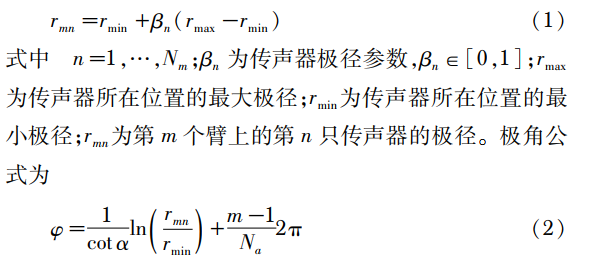

- 根据旋转的公式，成功实现，先计算出一个单臂的8维的半径数组，再通过半径数组和旋转角的到其他臂麦克风的位置`rmax = 0.08;`

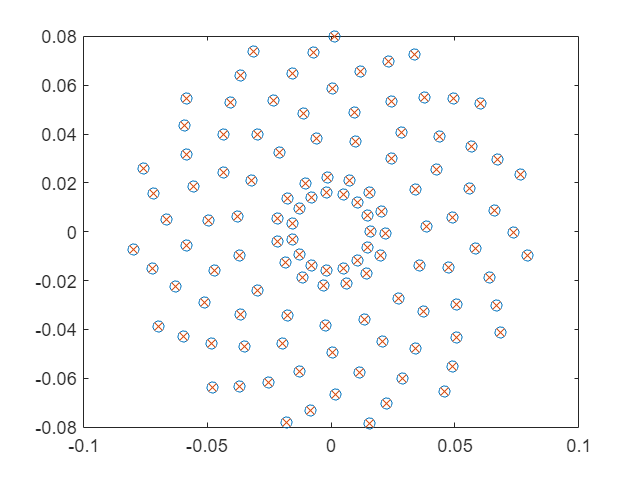

r0 = 0.016;

alpha = 4.2/6 * pi;
Na = 15;%15个臂
Nm = 8; %每个臂上8个麦克风
[x1, y1] = CreateUnderbrink2( Na,Nm,alpha, rmax, r0);
n = 2:Nm;
r1n=zeros(1,Nm);
r1n(1)=r0;
r1n(2:Nm)=sqrt((2*n-3)/(2*Nm-3))*rmax;%实现单臂的半径大小生成
phey1 = log(r1n/r0)/cot(alpha);%+(m-1)/Na*2*pi;
thetaMN = zeros(Nm, Na);
rmn = zeros(Nm, Na);
for m = 1:Na
    thetaMN(:,m)=phey1+(m-1)/Na*2*pi;%每个臂旋转角度
    rmn(:,m)=r1n;
end
rmn = reshape(rmn, 1, []);
thetaMN = reshape(thetaMN, 1, []);
x=rmn.*cos(thetaMN);
y=rmn.*sin(thetaMN);
figure;
plot(x,y,'o');

hold on
plot(x1,y1,'x');

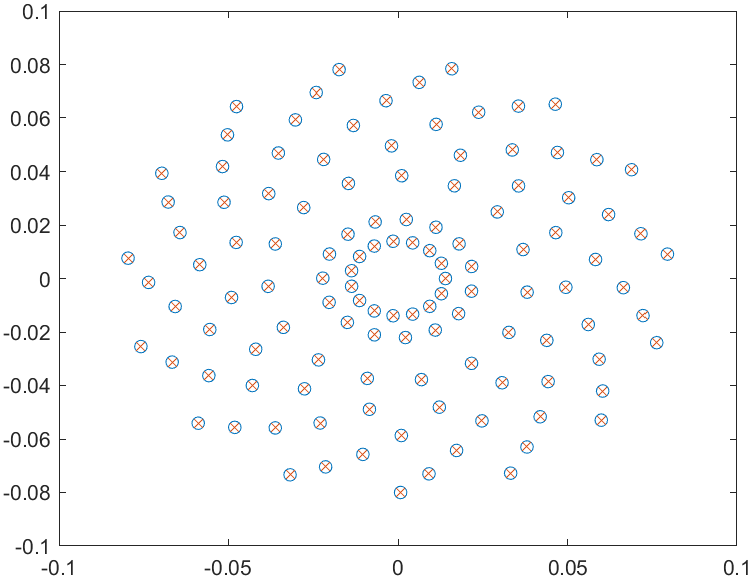

## 三.实现多目标优化函数

- 多目标优化，定位两个优化目标，更低的MSL和更低的3db带宽，在1KHz到15KHz范围取平均值，最为优化的适应度

-   y是目标函数向量。有几个目标函数y就有多少个维度（数组y的长度） 因为gamultiobj是以目标函数分量取极小值为目标，所以正好使用该取值方法

    y(1)=Average_MSL;
	y(2)=Average_3DB;

- 输入是阵列的单臂半径数组，即种群中的个体变量，维度为8。

- 通过第二节中旋转臂的方法得到整个阵列的麦克风的半径向量rmn（1X120）

- 将rmn输入到计算MSL和3db的计算式中，并求平均，分别得到Average_MSL，Average_3DB。

- 对于Average_MSL使用加权平均，MSL在中、高频段会急剧上升，采用随频率变化的权重，频率越高，权重越大，以期获得阵列在整个宽频范围内的良好抗干扰性

% function y=Fun(x)
% 	% y是目标函数向量。有几个目标函数y就有多少个维度（数组y的长度）
% 	% 因为gamultiobj是以目标函数分量取极小值为目标，
% 	% 因此有些取极大值的目标函数注意取相反数
%     Na = 15;%15个臂
%     Nm = 8; %每个臂上8个麦克风
%     r0=x(1);
%     alpha = 4.2/6 * pi;
% 	phey1 = log(x/r0)/cot(alpha);%+(m-1)/Na*2*pi;
% thetaMN = zeros(Nm, Na);
% rmn = zeros(Nm, Na);
% for m = 1:Na
%     thetaMN(:,m)=phey1+(m-1)/Na*2*pi;
%     rmn(:,m)=x;
% end
% 
% rmn = reshape(rmn, 1, []);
% thetaMN = reshape(thetaMN, 1, []);
% 
% x1=rmn.*cos(thetaMN);
% y1=rmn.*sin(thetaMN);
% ux = -1/sqrt(2):sqrt(2)/200:1/sqrt(2);
% uy = -1/sqrt(2):sqrt(2)/200:1/sqrt(2);
% f = 5000:500:50000;
% w=f/sum(f);%权重系数
% MSL = zeros(1, size(f,2));
% BW = zeros(1, size(f,2));
% 
% for i = (1:size(f,2))
%     Beam = anyBeam(x1, y1, f(i), -30, ux, uy, 'dB');
%     BW(1,i) = search3db(ux, uy, Beam, f(i));
%     [MSL(1,i),~,~] = findMSL(ux, uy, Beam);
% end
% Average_MSL=sum(MSL.*w); %加权平均,越高频率越关注
% Average_3DB=mean(BW);
% y(1)=Average_MSL;
% y(2)=Average_3DB;
% end


- **接下来做一个对比，看同样的是否生成的y数组是否相等**

rmax = 0.08;
r0 = 0.016;
% beta = 0:0.005:1;% 待定参数？？
alpha = 4.2/6 * pi; %待定参数？？
Na = 15;%15个臂
Nm = 8; %每个臂上8个麦克风

[x1, y1] = CreateUnderbrink2( Na,Nm,alpha, rmax, r0);

ux = -1/sqrt(2):sqrt(2)/200:1/sqrt(2);
uy = -1/sqrt(2):sqrt(2)/200:1/sqrt(2);
f = 5000:500:50000;
MSL = zeros(1, size(f,2));
BW = zeros(1, size(f,2));

for i = (1:size(f,2))
    Beam = anyBeam(x1, y1, f(i), -30, ux, uy, 'dB');
    BW(1,i) = search3db(ux, uy, Beam, f(i));
    [MSL(1,i),~,~] = findMSL(ux, uy, Beam);
end
y0(1)=mean(MSL);
y0(2)=mean(BW);

n = 2:Nm;
r1n=zeros(1,Nm);
r1n(1)=r0;
r1n(2:Nm)=sqrt((2*n-3)/(2*Nm-3))*rmax;


y=Fun(r1n);%定义在Fun.m中


   1



isEqual12 = isequal(y0, y);
disp(isEqual12);

- **得到结果isEqual12的值为1**

- 

- 验证得到Fun函数可以得到两个目标优化的适应值

## 四.确定变量的上下限和约束条件

    基圆的半径应该大于一定的值，如0.014m，因为半径太小，在物理排布上，15个麦克风风可能没法实现，同时基于underbrink阵列，基圆半径不能大于r2半径，且考虑物理实现，两个麦克风之间的半径至少大于0.005m

-    r2半径由rmax决定   r2=0.277*rmax

-   则基圆半径0.014 < r0 < 0.277*rmax-0.005

- 处基圆外后续每一个半径的下界都应该是由ramx=0.08决定的半径值

- 上界是后一个半径的下界减去0.005

lb=[0.014  ,0.0222 ,0.0384 , 0.0496 , 0.0587 , 0.0666 , 0.0736, 0.0800];
ub=[0.0172 ,0.0334 ,0.0446 , 0.0537 , 0.0616 , 0.0686 , 0.0750, 0.085];


**仅通过上下界来约束，已经限定了整个阵列阵元可变化的范围，无须其他约束条件，毕竟阵元位置和求的目标是强非线性关系**

## **四。初步优化结果**

**选取了15个臂，每个臂上8个麦克风来优化，后面发现时间复杂度太高了，前面种群数选的过大，代数也比较大，预估一周才能结束，重新选择种群数30，迭代200代**

**最后优化结果**

**单臂位置，x=0.0151028419069376	0.0297831095101247	0.0443786127634653	0.0531537977763643	0.0603245941811392	0.0674531179791436	0.0737506798023954	0.0845113027272731**

**最优的pareto前沿**

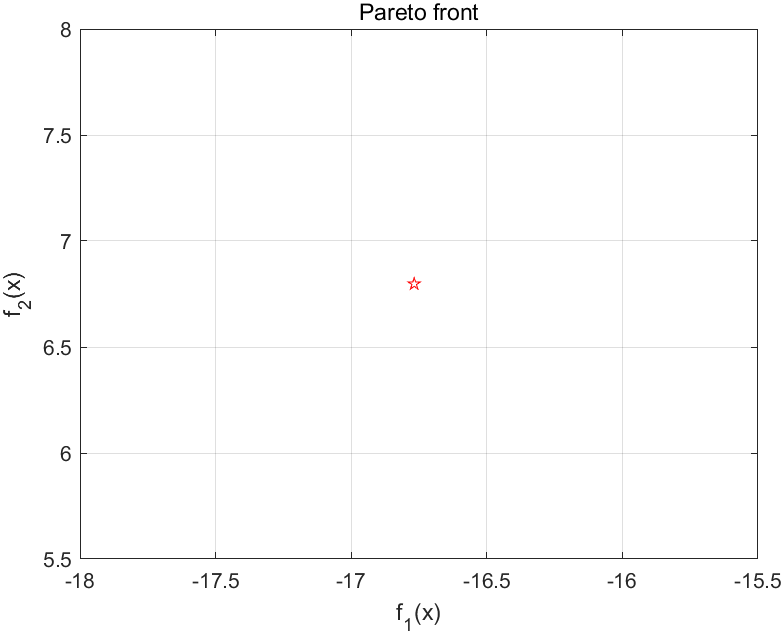

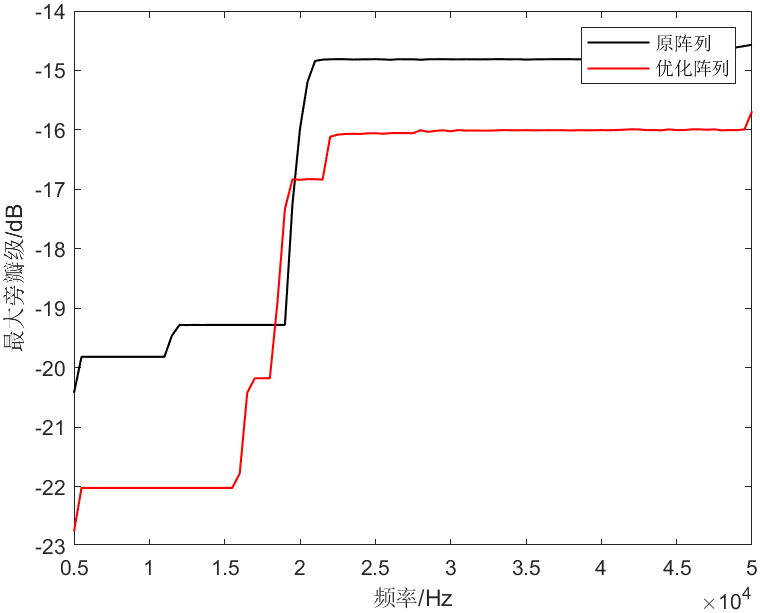

### 与原始的rmax=0.08 rmin=0.016对比

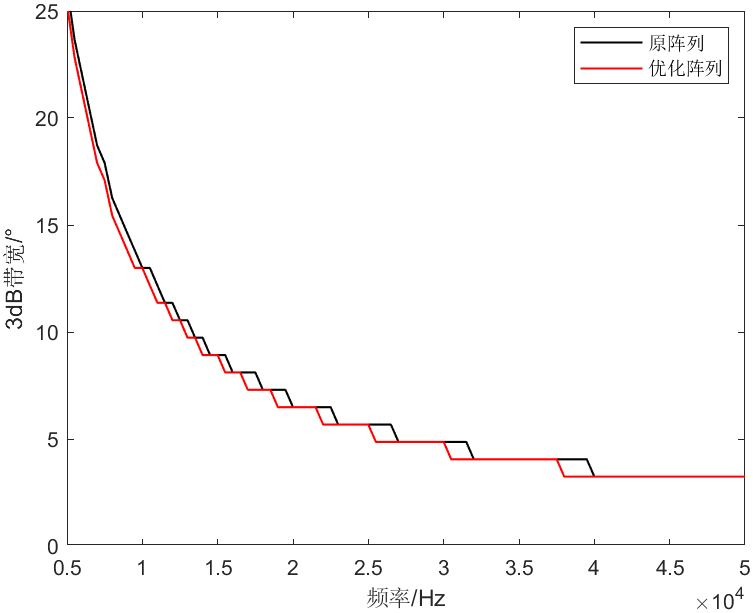

但是这个是增加了阵列的孔径

而两个阵列**各自再加内圈0.012处一环**8个麦克风，**反而MSL性能变差**，3db性能没差别，后续直接加入圆环到FUN函数中取fitness值来优化，并且优化上下限的配置。

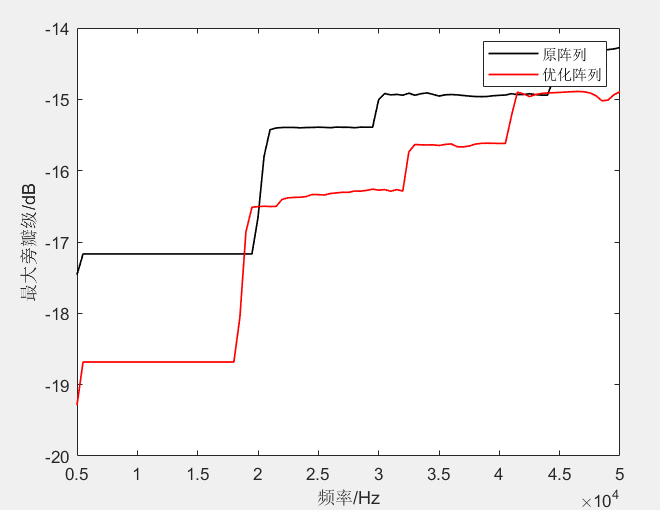

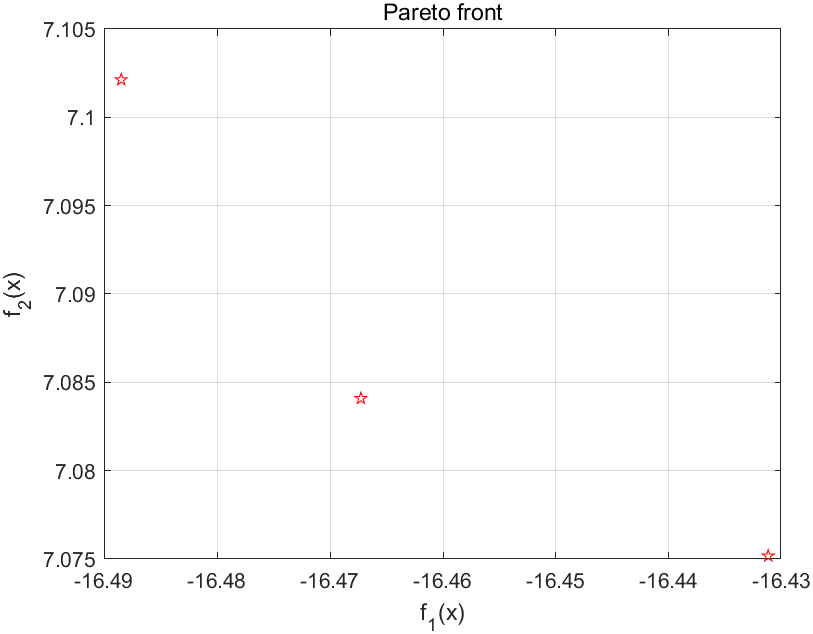

0.0163222159092275	0.0298786971099533	0.0417934128981190	0.0528809359617759	0.0609002247878298	0.0667982082457355	0.0745606591246190	0.0800000000000000

0.0164609176632111	0.0300536401061617	0.0416651388748513	0.0532609053751513	0.0609970053061374	0.0672735897972116	0.0752221407284317	0.0800000000000000

0.0163919390335892	0.0299742900689528	0.0417629735843558	0.0529620042279050	0.0609310599854901	0.0668769590662625	0.0746542908603356	0.0800000000000000